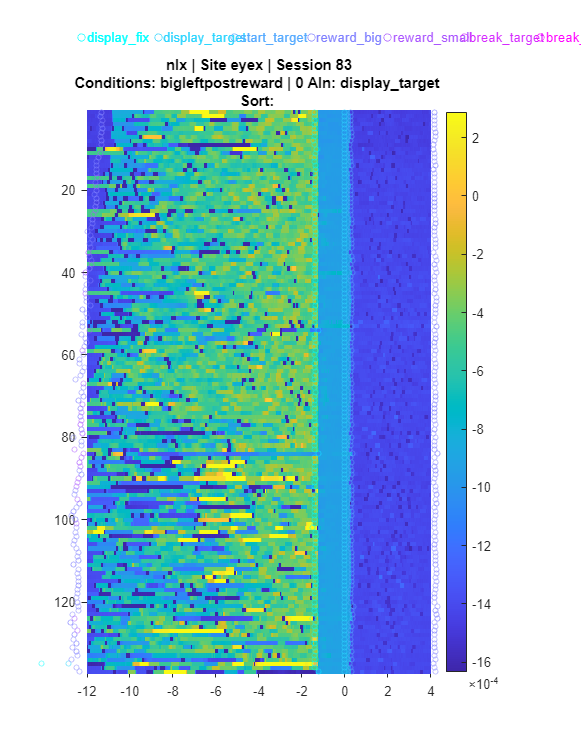

%get eyex data
[axaR,tridsR,dataR,stamps]=tr_raster(trlists,'nlx','eyex','ttypes',{{'big','left'},{'post','reward'}},'win',[-12,4],'event','display_target');

% trim data to desired window
dataR2={};
for i= 1:size(dataR,1)
    dataR2{i}=dataR(i,12000:12000+(stamps(i,3)*1000));
end

%calculate velo
velo={};
peakVelo=[];
for i= 1:size(dataR2,2)
    velo{i}=diff(abs(dataR2{i}));
    peaks{i}=max(velo{i});
    peakVelo=cell2mat(peaks);
end
peakVelo=peakVelo(:);
peakVeloscrubbed=rmoutliers(peakVelo);


%calculate mag
Mag={};
for i= 1:size(dataR2,2)
    hol{1}=dataR2{i};
    hold=cell2mat(hol);
    Mag{i}=hold(1,1)-hold(1,end);
end
Mags=cell2mat(Mag);
Mags=Mags(:);

%% get the ids and split them into quartiles%
%tridsR=[tridsR(:,1:3) tridsR(:,5:end)];
%tridsR=[tridsR(:,1:29) tridsR(:,31:end)];
%peakVelo=[peakVelo(1:3,:); peakVelo(5:end,:)];
%peakVelo=[peakVelo(1:29,:); peakVelo(31:end,:)];
%Mags=[Mags(1:3,:); Mags(5:end,:)];
%Mags=[Mags(1:29,:); Mags(31:end,:)];
velo_ids=[tridsR(:) PeakVSR];
% until mag fixed Mags_ids=[tridsR(:) Mags(:)];

%peak_velo_scrubbed_ids=rmoutliers(velo_ids(:,2)); doesnt work like i
%thought.

%peak_velo_scrubbed_ids=[velo_ids(1:18,:);velo_ids(19:end,:)]
%peak_velo_scrubbed=velo_ids;
Vquant=quantile(velo_ids(:,2),4);
%Vquant=quantile(peak_velo_scrubbed_ids(:,2),4)
% until mag fixed Mquant=quantile(Mags_ids(:,2),4)

%get the quartile corresponding IDS to get the appropriate DA data

firstquantveloids=velo_ids(find(velo_ids(:,2)<Vquant(1)));
fourthquantveloids=velo_ids(find(velo_ids(:,2)>Vquant(4)));


firstquantmagids=Mags_ids(find(Mags_ids(:,2)<Mquant(1)));

Unrecognized function or variable 'Mags_ids'.

fourthquantmagids=Mags_ids(find(Mags_ids(:,2)>Mquant(4)));


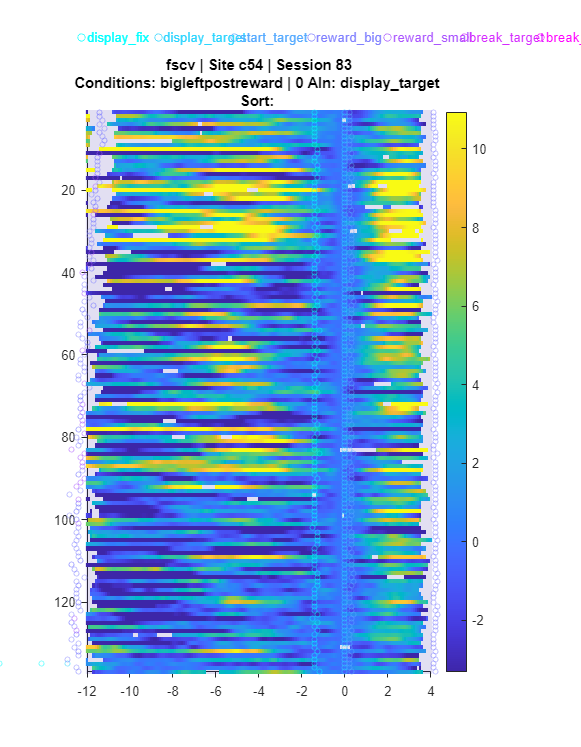

%get the dopamine data 
[axa,tridsT,dataT]=tr_raster(trlists,'fscv','da',4,'ttypes',{{'big','left'},{'post','reward'}},'win',[-12,4],'event','display_target');

%split the DA data by the appropriate trial IDS
labeled_data=[tridsT(:) dataT];

fquantDAvelo=[];
lquantDAvelo=[];
fquantDAmag=[];
lquantDAmag=[];

% for i= 1:size(firstquantmagids)
%     fquantDAmag(i,:)=labeled_data(find(labeled_data(:,1)==firstquantmagids(i)),:);
% end
% fquantDAmag=fquantDAmag(:,2:end);
% 
% for i= 1:size(fourthquantmagids)
%     lquantDAmag(i,:)=labeled_data(find(labeled_data(:,1)==fourthquantmagids(i)),:);
% end
% lquantDAmag=lquantDAmag(:,2:end);

for i= 1:size(firstquantveloids)
    fquantDAvelo(i,:)=labeled_data(find(labeled_data(:,1)==firstquantveloids(i)),:);
end
fquantDAvelo=fquantDAvelo(:,2:end);

for i= 1:size(firstquantveloids)
    lquantDAvelo(i,:)=labeled_data(find(labeled_data(:,1)==fourthquantveloids(i)),:);
end
lquantDAvelo=lquantDAvelo(:,2:end);


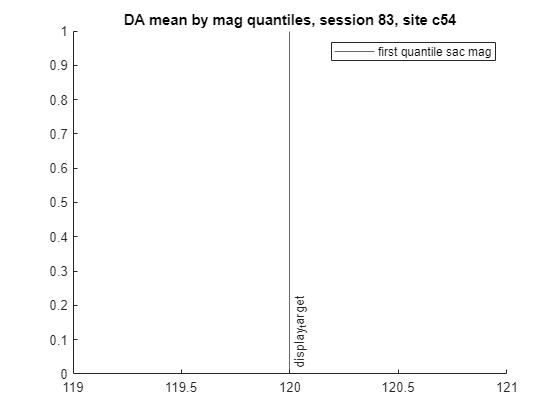

%get means and SE and plot mag
fqmag_mean=nanmean(fquantDAmag,1);
lqmag_mean=nanmean(lquantDAmag,1);
fqmag_SE=nanstd(fquantDAmag,0,1)./sqrt(28);
lqmag_SE=nanstd(lquantDAmag,0,1)./sqrt(28);


figure; plot(fqmag_mean,'-b')
hold on; plot(lqmag_mean,'-r')
hold on; plot(lqmag_mean+lqmag_SE,'-k')
hold on; plot(lqmag_mean-lqmag_SE,'-k')
hold on; plot(fqmag_mean+fqmag_SE,'-k')
hold on; plot(fqmag_mean-fqmag_SE,'-k')
title("DA mean by mag quantiles, session 83, site c54")
x3=xline(120,'-',{'display_target'});
x3.LabelVerticalAlignment = 'bottom';
legend("first quantile sac mag","last quantile sac mag")

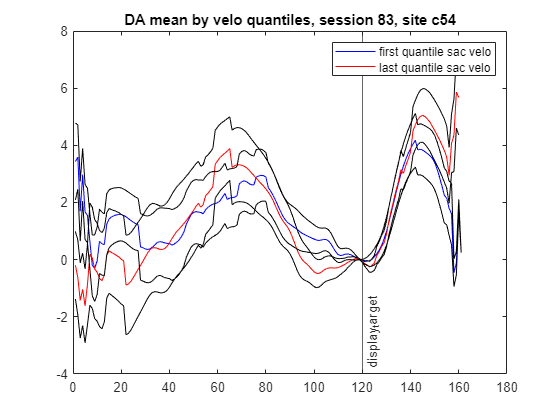


fqvelo_mean=nanmean(fquantDAvelo,1);
lqvelo_mean=nanmean(lquantDAvelo,1);
fqvelo_SE=nanstd(fquantDAvelo,0,1)./sqrt(27);
lqvelo_SE=nanstd(lquantDAvelo,0,1)./sqrt(27);

figure; plot(fqvelo_mean,'-b')
hold on; plot(lqvelo_mean,'-r')
hold on; plot(lqvelo_mean+lqvelo_SE,'-k') 
hold on; plot(lqvelo_mean-lqvelo_SE,'-k')
hold on; plot(fqvelo_mean+fqvelo_SE,'-k')
hold on; plot(fqvelo_mean-fqvelo_SE,'-k')
title("DA mean by velo quantiles, session 83, site c54" + ...
    "")
x3=xline(120,'-',{'display_target'});
x3.LabelVerticalAlignment = 'bottom';
legend("first quantile sac velo","last quantile sac velo")